clc;
clear;
close all;

%% ============================================================
%        HALF BULKHEAD - SYMBOLIC CASTIGLIANO FRAME
%
% Geometry:
%
%        1 ---------------- 2
%                           |
%                           |
%                           |
%                           |
%                           3
%
% Only TOP + SIDE members are present.
%
% Right half of bulkhead is considered.
% ============================================================

%% ---------------- SYMBOLIC VARIABLES ----------------

syms x s real

% Unknowns at the lower end / skin connection
syms F3 V3 M3 real

% Applied lift on right half
syms L real

% Material properties
syms E G real

% Section properties
syms I A As real


%% ============================================================
%                    GEOMETRY
% ============================================================

a = sym(0.09);        % Half-width of bulkhead [m]
h = sym(0.25);        % Height of bulkhead [m]


%% ============================================================
%                    LOAD FUNCTIONS
% ============================================================

% ------------------------------------------------------------
% Distributed load on TOP MEMBER
%
% Replace this with your actual q(x) equation.
%
% Example:
%
% q(x) = q2*x^2 + q1*x + q0
%
% ------------------------------------------------------------

syms q0 q1 q2 real

q_top = q2*x^2 + q1*x + q0;


% ------------------------------------------------------------
% Distributed load on SIDE MEMBER
%
% Replace with your actual vertical-wall shear-flow equation.
% ------------------------------------------------------------

syms qs0 qs1 qs2 real

q_side = qs2*s^2 + qs1*s + qs0;


%% ============================================================
%                PRINT q(x) EQUATIONS
% ============================================================

fprintf('\n============================================\n');

fprintf('SYMBOLIC SHEAR-FLOW / DISTRIBUTED LOAD\n');

SYMBOLIC SHEAR-FLOW / DISTRIBUTED LOAD


fprintf('============================================\n');


fprintf('\nTop-member q(x):\n');


Top-member q(x):


disp(q_top);

$$q_{2}\,x^{2}+q_{1}\,x+q_{0}$$


fprintf('\nSide-member q_s(s):\n');


Side-member q_s(s):


disp(q_side);

$${\mathrm{qs}}_{2}\,s^{2}+{\mathrm{qs}}_{1}\,s+{\mathrm{qs}}_{0}$$



%% ============================================================
%           MEMBER 1 : TOP HORIZONTAL MEMBER
% ============================================================
%
% Coordinate:
%
%       1 -------------------- 2
%       <-------  x ---------->
%
% x = 0 at point 1
% x = a at point 2
%
% Lift acts at point 1:
%
%             L/2
%              ↓
%       1 ---------------- 2
%
% ------------------------------------------------------------


% Resultant of distributed load between 0 and x
Qtop = int(q_top, x, 0, x);

% First moment of distributed load about section x
Mtop_load = int(q_top*(x - sym('xi')), ...
               sym('xi'), 0, x);


%% ------------------------------------------------------------
% TOP MEMBER INTERNAL FORCES
%
% Sign convention is chosen consistently for this model.
% ------------------------------------------------------------

% Vertical shear
V1 = -L/2 + Qtop;

% Axial force
N1 = F3;

% Bending moment
M1 = M3 + V3*x + ...
     int(q_top*(x - sym('xi')), ...
     sym('xi'), 0, x);


%% ============================================================
%              MEMBER 2 : VERTICAL MEMBER
% ============================================================
%
%       2
%       |
%       |
%       |
%       |
%       3
%
% s = 0 at point 2
% s = h at point 3
%
% ------------------------------------------------------------


% Resultant distributed side load
Qside = int(q_side, s, 0, s);

% First moment of side loading
Mside_load = int(q_side*(s - sym('eta')), ...
                 sym('eta'), 0, s);


%% ------------------------------------------------------------
% VERTICAL MEMBER INTERNAL FORCES
% ------------------------------------------------------------

% Axial force
N2 = V3 + Qside;

% Horizontal shear force
V2 = F3;

% Bending moment
M2 = M3 + F3*s + ...
     int(q_side*(s - sym('eta')), ...
     sym('eta'), 0, s);


%% ============================================================
%          DISPLAY INTERNAL FORCE EQUATIONS
% ============================================================

fprintf('\n============================================\n');

fprintf('INTERNAL FORCE EQUATIONS\n');

INTERNAL FORCE EQUATIONS


fprintf('============================================\n');


fprintf('\nTOP MEMBER:\n');


TOP MEMBER:



fprintf('\nAxial N1(x) =\n');


Axial N1(x) =


disp(simplify(N1));

$$F_{3}$$


fprintf('\nShear V1(x) =\n');


Shear V1(x) =


disp(simplify(V1));

$$\frac{q_{2}\,x^{3}}{3}+\frac{q_{1}\,x^{2}}{2}+q_{0}\,x-\frac{L}{2}$$


fprintf('\nMoment M1(x) =\n');


Moment M1(x) =


disp(simplify(M1));

$$M_{3}+V_{3}\,x+\frac{x^{2}\,\left(q_{2}\,x^{2}+q_{1}\,x+q_{0}\right)}{2}$$



fprintf('\nVERTICAL MEMBER:\n');


VERTICAL MEMBER:



fprintf('\nAxial N2(s) =\n');


Axial N2(s) =


disp(simplify(N2));

$$\frac{{\mathrm{qs}}_{2}\,s^{3}}{3}+\frac{{\mathrm{qs}}_{1}\,s^{2}}{2}+{\mathrm{qs}}_{0}\,s+V_{3}$$


fprintf('\nShear V2(s) =\n');


Shear V2(s) =


disp(simplify(V2));

$$F_{3}$$


fprintf('\nMoment M2(s) =\n');


Moment M2(s) =


disp(simplify(M2));

$$M_{3}+F_{3}\,s+\frac{s^{2}\,\left({\mathrm{qs}}_{2}\,s^{2}+{\mathrm{qs}}_{1}\,s+{\mathrm{qs}}_{0}\right)}{2}$$



%% ============================================================
%                  STRAIN ENERGY
% ============================================================

U1 = int( M1^2/(2*E*I), s, 0, a );

clc;
clear;
close all;

%% ============================================================
%             HALF BULKHEAD ANALYSIS
%         SYMBOLIC MATLAB IMPLEMENTATION
%
% Geometry:
%
%                 L/2
%                  ↓
%       1 -------------------- 2
%                              |
%                              |
%                              |
%                              |
%                              3
%
% Right half of bulkhead
% Top + vertical side only
%
% No bottom member
% ============================================================


%% ============================================================
% 1. SYMBOLIC VARIABLES
% ============================================================

syms x s xi eta real

% Unknown force resultants at point 3
syms F3 V3 M3 real

% Load
syms L real

% Material
syms E G real

% Section properties
syms I A As real


%% ============================================================
% 2. GEOMETRY
% ============================================================

a = sym(0.09);      % Top half-width [m]
h = sym(0.25);      % Side height [m]


%% ============================================================
% 3. DISTRIBUTED LOADS
% ============================================================

% ------------------------------------------------------------
% TOP MEMBER q(x)
%
% Replace q0, q1, q2 with your actual values.
%
% For example, the previous report used:
%
% q(x) = -12.534*x^2 + 2.2543*x + 44.4996
%
% ------------------------------------------------------------

syms q0 q1 q2 real

q_top = q2*x^2 + q1*x + q0;


% ------------------------------------------------------------
% SIDE MEMBER q_s(s)
%
% Replace this with your actual shear-flow equation.
% ------------------------------------------------------------

syms r0 r1 r2 real

q_side = r2*s^2 + r1*s + r0;


%% ============================================================
% 4. PRINT q EQUATIONS
% ============================================================

fprintf('\n');
fprintf('====================================================\n');

fprintf(' DISTRIBUTED LOAD / SHEAR FLOW EQUATIONS\n');

 DISTRIBUTED LOAD / SHEAR FLOW EQUATIONS


fprintf('====================================================\n');


fprintf('\nTop member:\n');


Top member:


q_top = expand(q_top);
disp(q_top);

$$q_{2}\,x^{2}+q_{1}\,x+q_{0}$$


fprintf('\nSide member:\n');


Side member:


q_side = expand(q_side);
disp(q_side);

$$r_{2}\,s^{2}+r_{1}\,s+r_{0}$$



%% ============================================================
% 5. MEMBER 1 : TOP MEMBER
% ============================================================
%
% Coordinate:
%
%       1 -------------------- 2
%       <--------- x --------->
%
% x = 0 at point 1
% x = a at point 2
%
% ------------------------------------------------------------


% Resultant of q_top between 0 and x
Q_top = int(q_top, x);

% First moment of q_top about section x
% Use dummy variable xi
Q_top_x = int(subs(q_top,x,xi)*(x-xi),xi,0,x);


%% ------------------------------------------------------------
% Internal shear force in top member
%
% L/2 is the half-bulkhead lift.
% ------------------------------------------------------------

V_top = -L/2 + int(q_top, x, 0, x);


%% ------------------------------------------------------------
% Internal axial force in top member
%
% F3 is the horizontal force transmitted by the side.
% ------------------------------------------------------------

N_top = F3;


%% ------------------------------------------------------------
% Internal bending moment in top member
% ------------------------------------------------------------

M_top = M3 ...
      + V3*x ...
      - int(subs(q_top,x,xi)*(x-xi),xi,0,x);

M_top = simplify(M_top);


%% ============================================================
% 6. MEMBER 2 : VERTICAL SIDE
% ============================================================
%
%       2
%       |
%       |
%       | s
%       |
%       3
%
% s = 0 at point 2
% s = h at point 3
%
% ------------------------------------------------------------


%% ------------------------------------------------------------
% Resultant side load
% ------------------------------------------------------------

Q_side = int(q_side,s,0,s);


%% ------------------------------------------------------------
% Internal horizontal shear
% ------------------------------------------------------------

V_side = F3;


%% ------------------------------------------------------------
% Internal axial force
% ------------------------------------------------------------

N_side = V3 + Q_side;


%% ------------------------------------------------------------
% Internal bending moment
% ------------------------------------------------------------

M_side = M3 ...
       + F3*s ...
       - int(subs(q_side,s,eta)*(s-eta),eta,0,s);

M_side = simplify(M_side);


%% ============================================================
% 7. PRINT INTERNAL FORCE EQUATIONS
% ============================================================

fprintf('\n');
fprintf('====================================================\n');

fprintf(' TOP MEMBER INTERNAL FORCE EQUATIONS\n');

 TOP MEMBER INTERNAL FORCE EQUATIONS


fprintf('====================================================\n');


fprintf('\nN_top(x) = \n');


N_top(x) = 


disp(simplify(N_top));

$$F_{3}$$


fprintf('\nV_top(x) = \n');


V_top(x) = 


disp(simplify(V_top));

$$\frac{q_{2}\,x^{3}}{3}+\frac{q_{1}\,x^{2}}{2}+q_{0}\,x-\frac{L}{2}$$


fprintf('\nM_top(x) = \n');


M_top(x) = 


disp(simplify(M_top));

$$M_{3}+V_{3}\,x-\frac{x^{2}\,\left(q_{2}\,x^{2}+2\,q_{1}\,x+6\,q_{0}\right)}{12}$$



fprintf('\n');
fprintf('====================================================\n');

fprintf(' SIDE MEMBER INTERNAL FORCE EQUATIONS\n');

 SIDE MEMBER INTERNAL FORCE EQUATIONS


fprintf('====================================================\n');


fprintf('\nN_side(s) = \n');


N_side(s) = 


disp(simplify(N_side));

$$\frac{r_{2}\,s^{3}}{3}+\frac{r_{1}\,s^{2}}{2}+r_{0}\,s+V_{3}$$


fprintf('\nV_side(s) = \n');


V_side(s) = 


disp(simplify(V_side));

$$F_{3}$$


fprintf('\nM_side(s) = \n');


M_side(s) = 


disp(simplify(M_side));

$$M_{3}+F_{3}\,s-\frac{s^{2}\,\left(r_{2}\,s^{2}+2\,r_{1}\,s+6\,r_{0}\right)}{12}$$



%% ============================================================
% 8. STRAIN ENERGY
% ============================================================

% Bending energy
U_bend_top = int( M_top^2/(2*E*I), x, 0, a );

U_bend_side = int( M_side^2/(2*E*I), s, 0, h );


% Axial energy
U_axial_top = int( N_top^2/(2*E*A), x, 0, a );

U_axial_side = int( N_side^2/(2*E*A), s, 0, h );


% Shear energy
U_shear_top = int( V_top^2/(2*G*As), x, 0, a );

U_shear_side = int( V_side^2/(2*G*As), s, 0, h );


% Total strain energy
U = simplify( ...
      U_bend_top + U_bend_side + ...
      U_axial_top + U_axial_side + ...
      U_shear_top + U_shear_side );


fprintf('\n');
fprintf('====================================================\n');

fprintf('TOTAL STRAIN ENERGY U =\n');

TOTAL STRAIN ENERGY U =


fprintf('====================================================\n');


disp(U);

$$\frac{9\,\left(1120000000000000000\,{M_{3}}^{2}+100800000000000000\,M_{3}\,V_{3}-3024000000000000\,M_{3}\,q_{0}-68040000000000\,M_{3}\,q_{1}-2449440000000\,M_{3}\,q_{2}+3024000000000000\,{V_{3}}^{2}-204120000000000\,V_{3}\,q_{0}-4898880000000\,V_{3}\,q_{1}-183708000000\,V_{3}\,q_{2}+3674160000000\,{q_{0}}^{2}+183708000000\,q_{0}\,q_{1}+7085880000\,q_{0}\,q_{2}+2361960000\,{q_{1}}^{2}+186004350\,q_{1}\,q_{2}+3720087\,{q_{2}}^{2}\right)}{224000000000000000000\,\text{E}\,\text{I}}+\frac{9\,{F_{3}}^{2}}{200\,A\,\text{E}}+\frac{{F_{3}}^{2}}{8\,\mathrm{As}\,G}+\frac{9\,\left(1750000000000\,L^{2}-315000000000\,L\,q_{0}-9450000000\,L\,q_{1}-425250000\,L\,q_{2}+18900000000\,{q_{0}}^{2}+1275750000\,q_{0}\,q_{1}+61236000\,q_{0}\,q_{2}+22963500\,{q_{1}}^{2}+2296350\,q_{1}\,q_{2}+59049\,{q_{2}}^{2}\right)}{1400000000000000\,\mathrm{As}\,G}+\frac{1290240\,{V_{3}}^{2}+322560\,V_{3}\,r_{0}+26880\,V_{3}\,r_{1}+3360\,V_{3}\,r_{2}+26880\,{r_{0}}^{2}+5040\,r_{0}\,r_{1}+672\,r_{0}\,r_{2}+252\,{r_{1}}^{2}+70\,r_{1}\,r_{2}+5\,{r_{2}}^{2}}{10321920\,A\,\text{E}}+\frac{61931520\,{F_{3}}^{2}+743178240\,F_{3}\,M_{3}-11612160\,F_{3}\,r_{0}-774144\,F_{3}\,r_{1}-80640\,F_{3}\,r_{2}+2972712960\,{M_{3}}^{2}-61931520\,M_{3}\,r_{0}-3870720\,M_{3}\,r_{1}-387072\,M_{3}\,r_{2}+580608\,{r_{0}}^{2}+80640\,r_{0}\,r_{1}+8640\,r_{0}\,r_{2}+2880\,{r_{1}}^{2}+630\,r_{1}\,r_{2}+35\,{r_{2}}^{2}}{23781703680\,\text{E}\,\text{I}}$$



%% ============================================================
% 9. CASTIGLIANO EQUATIONS
% ============================================================
%
% IMPORTANT:
%
% For the OPEN half-bulkhead, this is only valid if
% F3, V3 and M3 are genuinely redundant unknowns associated
% with the specified compatibility constraints at point 3.
%
% ------------------------------------------------------------

eq1 = diff(U,F3) == 0;
eq2 = diff(U,V3) == 0;
eq3 = diff(U,M3) == 0;


fprintf('\n');
fprintf('====================================================\n');

fprintf('CASTIGLIANO EQUATIONS\n');

CASTIGLIANO EQUATIONS


fprintf('====================================================\n');


fprintf('\ndU/dF3 = 0:\n');


dU/dF3 = 0:


disp(eq1);

$$\frac{9\,F_{3}}{100\,A\,\text{E}}-\frac{11612160\,r_{0}-743178240\,M_{3}-123863040\,F_{3}+774144\,r_{1}+80640\,r_{2}}{23781703680\,\text{E}\,\text{I}}+\frac{F_{3}}{4\,\mathrm{As}\,G}=0$$


fprintf('\ndU/dV3 = 0:\n');


dU/dV3 = 0:


disp(eq2);

$$\frac{2580480\,V_{3}+322560\,r_{0}+26880\,r_{1}+3360\,r_{2}}{10321920\,A\,\text{E}}-\frac{9\,\left(204120000000000\,q_{0}-6048000000000000\,V_{3}-100800000000000000\,M_{3}+4898880000000\,q_{1}+183708000000\,q_{2}\right)}{224000000000000000000\,\text{E}\,\text{I}}=0$$


fprintf('\ndU/dM3 = 0:\n');


dU/dM3 = 0:


disp(eq3);

$$-\frac{61931520\,r_{0}-5945425920\,M_{3}-743178240\,F_{3}+3870720\,r_{1}+387072\,r_{2}}{23781703680\,\text{E}\,\text{I}}-\frac{9\,\left(3024000000000000\,q_{0}-100800000000000000\,V_{3}-2240000000000000000\,M_{3}+68040000000000\,q_{1}+2449440000000\,q_{2}\right)}{224000000000000000000\,\text{E}\,\text{I}}=0$$



%% ============================================================
% 10. SOLVE
% ============================================================

sol = solve([eq1,eq2,eq3],[F3,V3,M3], ...
            'ReturnConditions',true);


fprintf('\n');
fprintf('====================================================\n');

fprintf('CASTIGLIANO SOLUTION\n');

CASTIGLIANO SOLUTION


fprintf('====================================================\n');


disp(sol);

            F3: (A*As*G*(26572050000*A*q0 + 956593800*A*q1 + 43046721*A*q2 + 2893218750000*A*r0 + 211865625000*A*r1 + 23255859375*A*r2 - 218700000000000*I*q0 - 4920750000000*I*q1 - 177147000000*I*q2 + 3963750000000000*I*r0 + 268593750000000*I*r1 + 2761…
            V3: -(612000000000000000*A*E*I^2*r0 + 607500000000000*A^2*E*I*r0 + 51000000000000000*A*E*I^2*r1 + 37968750000000*A^2*E*I*r1 + 6375000000000000*A*E*I^2*r2 + 3796875000000*A^2*E*I*r2 + 220320000000000000*As*G*I^2*r0 + 18360000000000000*As*G*I…
            M3: (2239500000000000000*A*E*I^2*r0 + 1822500000000000*A^2*E*I*r0 + 147562500000000000*A*E*I^2*r1 + 113906250000000*A^2*E*I*r1 + 15515625000000000*A*E*I^2*r2 + 11390625000000*A^2*E*I*r2 + 31492800000000000*As*G*I^2*q0 + 708588000000000*As*G…
    parameters: [1×0 sym]
    conditions: 243*A + 250000*I ~= 0 & 25*A*As*G + 1200*A*E*I + 432*As*G*I ~= 0 & 15892200*E*A^2*I + 103275*As*G*A^2 + 20400000000*E*A*I^2 + 196346192*As*G*A*I + 7344000000*As*G*I^2 ~= 0





%% ============================================================
% 11. MOMENT EQUATIONS AFTER SUBSTITUTION
% ============================================================

M_top_final = simplify( ...
    subs(M_top,[F3,V3,M3], ...
    [sol.F3(1),sol.V3(1),sol.M3(1)]) );

M_side_final = simplify( ...
    subs(M_side,[F3,V3,M3], ...
    [sol.F3(1),sol.V3(1),sol.M3(1)]) );


fprintf('\n');
fprintf('====================================================\n');

fprintf('FINAL MOMENT EQUATIONS\n');

FINAL MOMENT EQUATIONS


fprintf('====================================================\n');


fprintf('\nTop member M(x):\n');


Top member M(x):


disp(M_top_final);


fprintf('\nSide member M(s):\n');


Side member M(s):


disp(M_side_final);

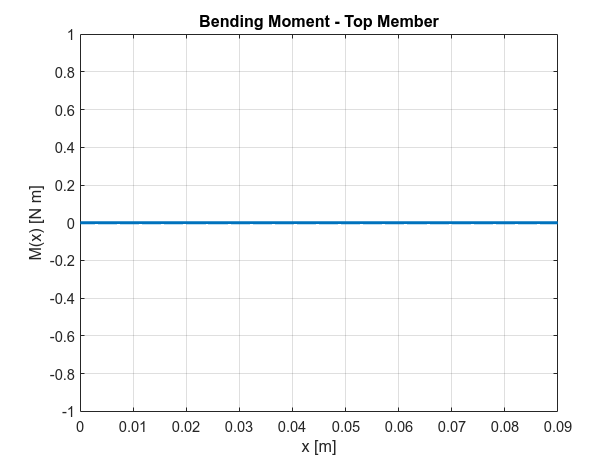



%% ============================================================
% 12. NUMERICAL SUBSTITUTION
% ============================================================
%
% Put actual material/load values here.
%
% Example:
%
% E_value  = 70e9;
% G_value  = 26e9;
% I_value  = ...;
% A_value  = ...;
% As_value = ...;
%
% and q(x) coefficients.
%
% ------------------------------------------------------------


%% ============================================================
% 13. PLOT SYMBOLIC MOMENT DISTRIBUTION
% ============================================================

% Example numerical placeholders ONLY for plotting.
% Replace these values by your actual data.

E_val  = 70e9;
G_val  = 26e9;

I_val  = 1e-9;
A_val  = 1e-4;
As_val = 1e-4;

L_val = 100;

q0_val = 0;
q1_val = 0;
q2_val = 0;

r0_val = 0;
r1_val = 0;
r2_val = 0;

Mtop_num = subs(M_top_final, ...
    [E G I A As L q0 q1 q2 r0 r1 r2], ...
    [E_val G_val I_val A_val As_val L_val ...
     q0_val q1_val q2_val r0_val r1_val r2_val]);

Mside_num = subs(M_side_final, ...
    [E G I A As L q0 q1 q2 r0 r1 r2], ...
    [E_val G_val I_val A_val As_val L_val ...
     q0_val q1_val q2_val r0_val r1_val r2_val]);


x_num = linspace(0,double(a),500);
s_num = linspace(0,double(h),500);

Mtop_plot = double(subs(Mtop_num,x,x_num));
Mside_plot = double(subs(Mside_num,s,s_num));


figure('Color','w');

plot(x_num,Mtop_plot,'LineWidth',2);
grid on;

xlabel('x [m]');
ylabel('M(x) [N m]');

title('Bending Moment - Top Member');

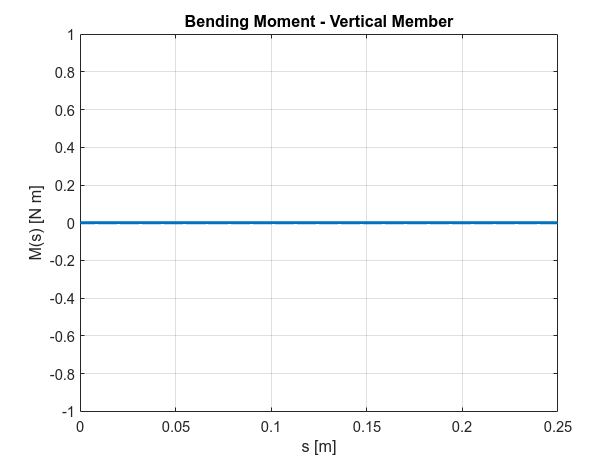



figure('Color','w');

plot(s_num,Mside_plot,'LineWidth',2);
grid on;

xlabel('s [m]');
ylabel('M(s) [N m]');

title('Bending Moment - Vertical Member');



%% ============================================================
% 14. MAXIMUM MOMENT
% ============================================================

Mmax_top  = max(abs(Mtop_plot));
Mmax_side = max(abs(Mside_plot));

Mmax = max(Mmax_top,Mmax_side);

fprintf('\n');
fprintf('====================================================\n');

fprintf('MAXIMUM BENDING MOMENT\n');

MAXIMUM BENDING MOMENT


fprintf('====================================================\n');


fprintf('Top member  Mmax = %.5f N-m\n',Mmax_top);

Top member  Mmax = 0.00000 N-m


fprintf('Side member Mmax = %.5f N-m\n',Mmax_side);

Side member Mmax = 0.00000 N-m


fprintf('Overall      Mmax = %.5f N-m\n',Mmax);

Overall      Mmax = 0.00000 N-m
